clc, clear; close all;

N = 500;
f1 = 50;
f2 = 38;

s1 = sin(linspace(0,f1,N));
s2 = sin(linspace(0,f2,N));
s = [s1;s2];

A = [0.8 0.5; 0.7 0.9];
x = A*s;

x_obsv = x;
x = x-repmat(mean(x,2),1,N);
R = (1/(N-1)*(x*x'))

R =     0.4276    0.4806
    0.4806    0.6198



[Y,sigma] = eig(R)

Y =    -0.7733    0.6340
    0.6340    0.7733


sigma =     0.0336         0
         0    1.0138


z = sqrt(inv(sigma))*Y'*x

z =    -0.0011   -0.0201   -0.0387   -0.0562   -0.0722   -0.0862   -0.0978   -0.1066   -0.1121   -0.1141   -0.1122   -0.1063   -0.0962   -0.0818   -0.0630   -0.0399   -0.0125    0.0190    0.0544    0.0933    0.1356    0.1807    0.2283    0.2777    0.3286    0.3803    0.4321    0.4835    0.5338    0.5823    0.6284    0.6714    0.7107    0.7455    0.7754    0.7997    0.8179    0.8295    0.8342    0.8316    0.8213    0.8031    0.7770    0.7428    0.7007    0.6505    0.5927    0.5274    0.4550    0.3759
   -0.0019    0.1788    0.3580    0.5342    0.7061    0.8721    1.0309    1.1813    1.3219    1.4517    1.5697    1.6748    1.7662    1.8433    1.9054    1.9521    1.9831    1.9982    1.9973    1.9806    1.9481    1.9004    1.8379    1.7611    1.6708    1.5679    1.4532    1.3279    1.1930    1.0497    0.8993    0.7431    0.5824    0.4185    0.2530    0.0872   -0.0776   -0.2400   -0.3986   -0.5522   -0.6995   -0.8395   -0.9709   -1.0929   -1.2045   -1.3050   -1.3935   -1.4696   -1.5328   -1

[V,~,~] = svd(kurtosis(z))

V = 1

W = V*sqrt(inv(sigma))*Y'*x

W =    -0.0011   -0.0201   -0.0387   -0.0562   -0.0722   -0.0862   -0.0978   -0.1066   -0.1121   -0.1141   -0.1122   -0.1063   -0.0962   -0.0818   -0.0630   -0.0399   -0.0125    0.0190    0.0544    0.0933    0.1356    0.1807    0.2283    0.2777    0.3286    0.3803    0.4321    0.4835    0.5338    0.5823    0.6284    0.6714    0.7107    0.7455    0.7754    0.7997    0.8179    0.8295    0.8342    0.8316    0.8213    0.8031    0.7770    0.7428    0.7007    0.6505    0.5927    0.5274    0.4550    0.3759
   -0.0019    0.1788    0.3580    0.5342    0.7061    0.8721    1.0309    1.1813    1.3219    1.4517    1.5697    1.6748    1.7662    1.8433    1.9054    1.9521    1.9831    1.9982    1.9973    1.9806    1.9481    1.9004    1.8379    1.7611    1.6708    1.5679    1.4532    1.3279    1.1930    1.0497    0.8993    0.7431    0.5824    0.4185    0.2530    0.0872   -0.0776   -0.2400   -0.3986   -0.5522   -0.6995   -0.8395   -0.9709   -1.0929   -1.2045   -1.3050   -1.3935   -1.4696   -1.5328   -1

s_hat = W.*x

s_hat =     0.0000   -0.0024   -0.0091   -0.0196   -0.0333   -0.0491   -0.0657   -0.0820   -0.0964   -0.1076   -0.1142   -0.1153   -0.1098   -0.0972   -0.0772   -0.0499   -0.0158    0.0242    0.0689    0.1168    0.1660    0.2146    0.2604    0.3013    0.3352    0.3601    0.3744    0.3767    0.3661    0.3422    0.3048    0.2546    0.1926    0.1204    0.0400   -0.0462   -0.1354   -0.2247   -0.3109   -0.3912   -0.4624   -0.5219   -0.5672   -0.5965   -0.6084   -0.6020   -0.5771   -0.5342   -0.4746   -0.3999
    0.0000    0.0245    0.0982    0.2188    0.3823    0.5835    0.8159    1.0719    1.3435    1.6218    1.8980    2.1633    2.4092    2.6281    2.8130    2.9582    3.0594    3.1134    3.1189    3.0758    2.9859    2.8520    2.6788    2.4718    2.2375    1.9834    1.7174    1.4477    1.1822    0.9290    0.6954    0.4879    0.3122    0.1727    0.0727    0.0140   -0.0027    0.0217    0.0851    0.1840    0.3143    0.4704    0.6464    0.8357    1.0316    1.2273    1.4160    1.5916    1.7483 

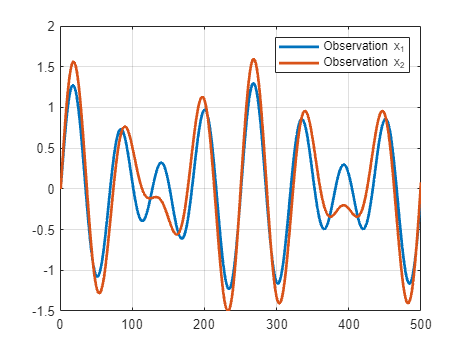


figure; plot(x','LineWidth',2); grid;
legend('Observation x_1', 'Observation x_2')